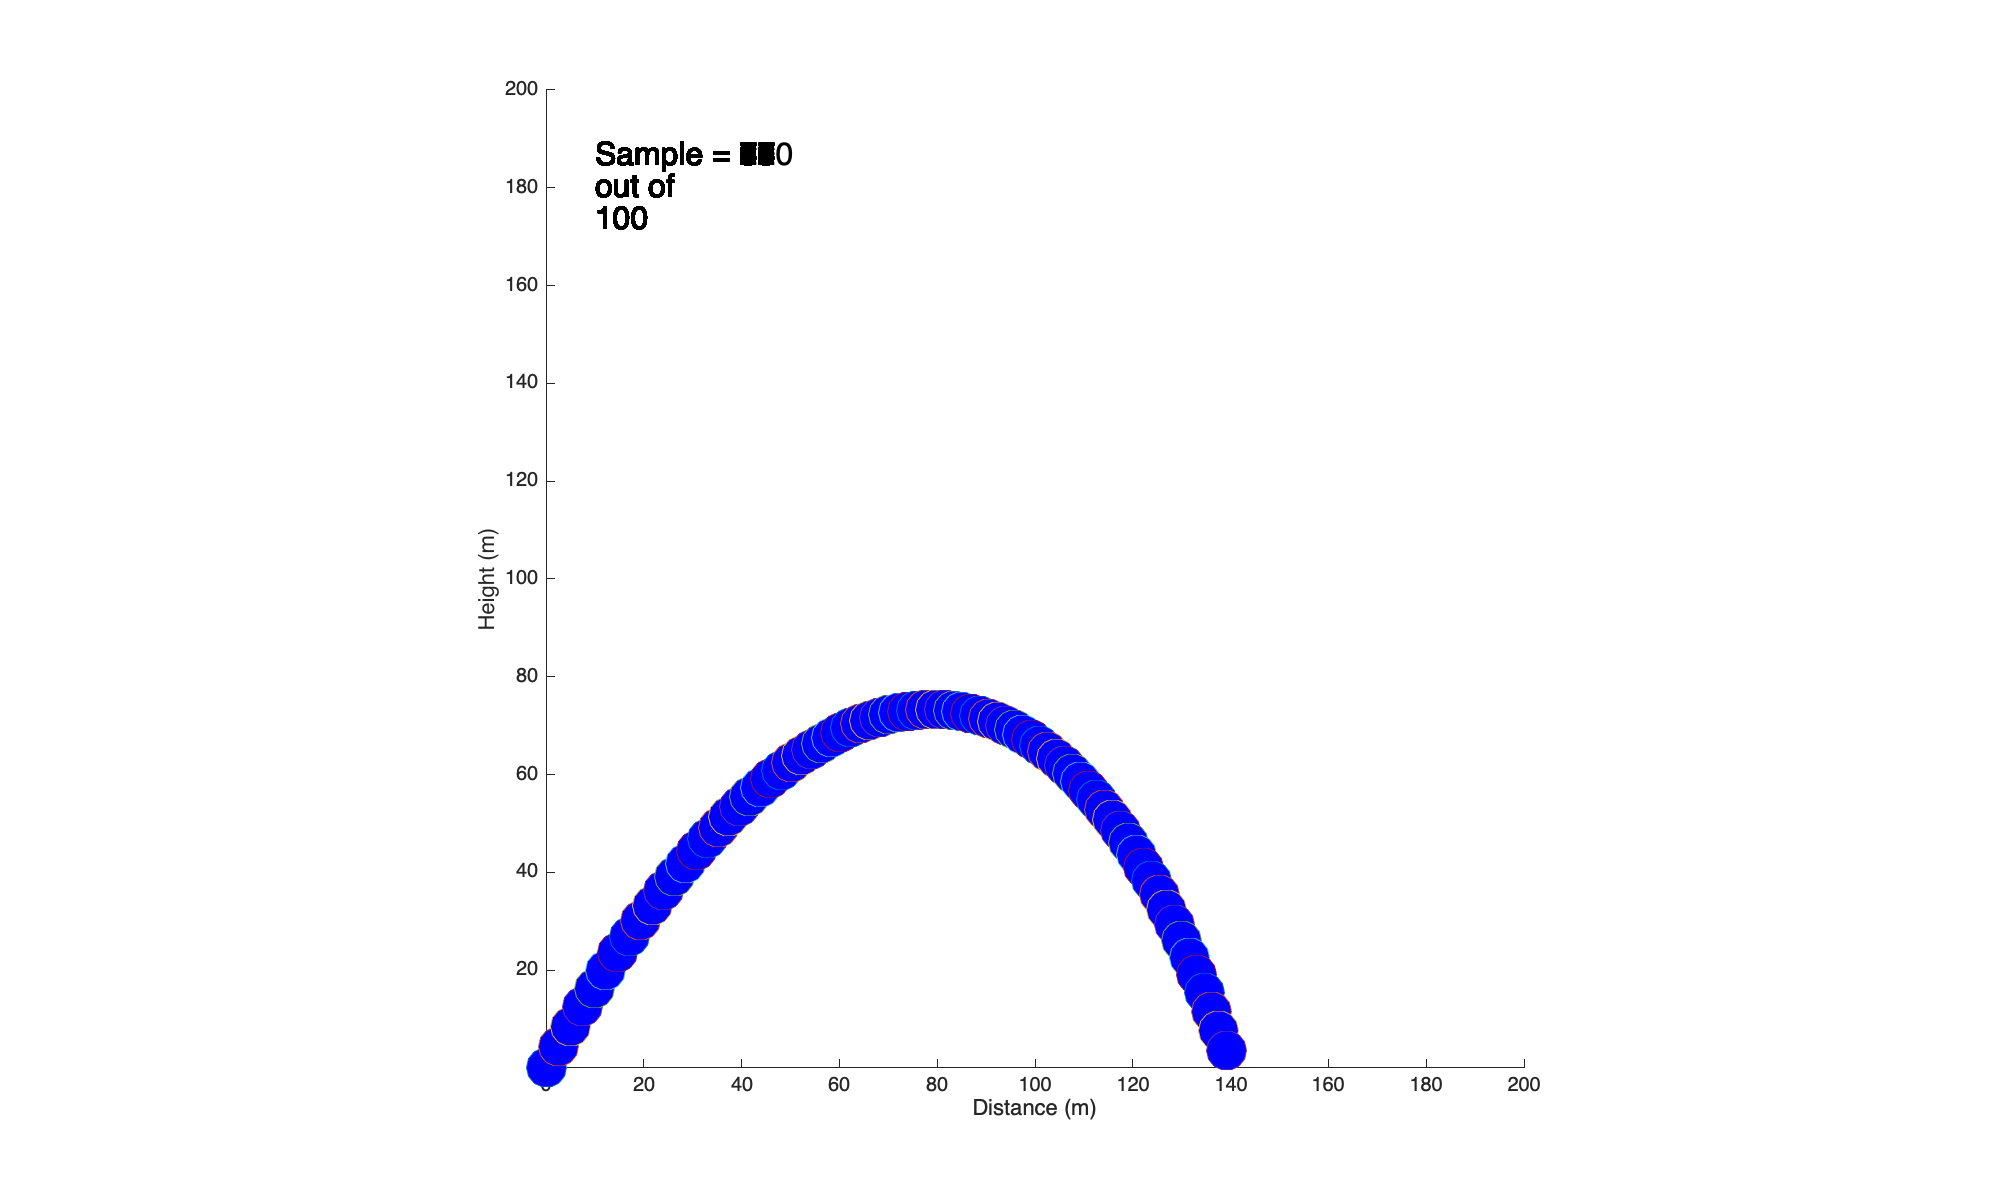

clear

%---------------------- User defined parameters------------------------
Cd = 0.47;                              % Drag coefficient

r = 0.2;                                % Projectile radius (m)
m = 10;                                 % Mass (kg)

v0 = 50;                                % Initial Velocity (m/s)
ang = 60;                               % Initial Angle (degrees)

Num_of_samples = 100;                   % Number of samples
ball_size = 20;                         % Size of the ball in the plot
%----------------------------------------------------------------------



%-------------------------- Air resistance ----------------------------

% Drag force:   Fd = (Cd * A * rho_air * V.^2)/2
%               Fd = m*a --> a = Fd / m
%               a = (Cd * A * rho_air * V.^2)/(2 * m)

A = pi * r * r;                         % Cross area (m^2)
rho_air = 1.28;                         % Air density (kg/m^3)
g = 9.81;                               % Gravity acceleration (m/s^2)
k = (Cd * A * rho_air) / (2 * m);       % Constant term for convenience
               % --> a = k * V.^2
%----------------------------------------------------------------------



%---------------- Initialize arrays to store resultss -----------------
tspan = [0, 50];

dt = 0.1;                  % Time step for Euler method
t = 0:dt:(Num_of_samples)*dt;

v_x = v0.* cosd(ang);       % Initial X Velocity (m/s)
v_y = v0.* sind(ang);       % Initial Y Velocity (m/s)

dx = zeros(1, length(t));
dy = zeros(1, length(t));
%----------------------------------------------------------------------



%----------------------------- Euler's Method --------------------------------
for i = 1:length(t)-1
    v_x(i + 1) = v_x(i) + dt * (-k * v_x(i).^2);       % next x_vel = x_vel + time step * x_acc
    v_y(i + 1) = v_y(i) + dt * (-k * v_y(i).^2 - g);   % next y_vel = y_vel + time step * y_acc
        
    dx(i + 1) = dx(i) + dt * v_x(i);                  % next x_pos = x_pos + time step * x_vel
    dy(i + 1) = dy(i) + dt * v_y(i);                  % next y_pos = y_pos + time step * y_vel
end
%-----------------------------------------------------------------------------



%------------------------------- Angle of attack -----------------------------
                            % (Not implemented yet)

K = 1;                      % Coefficient for affect of angle 
aoa = atan2(v_y, v_x);      % Calculate the angle the projectile has
Cd2 = Cd + K * aoa;         % Drag force based on the angle

%-----------------------------------------------------------------------------


%----------------------------- Animation --------------------------------
figure('Position',[100 50 1000 600]);   % create new figure

ax = gca;                               % get the current axis
axis equal                              % use same length per unit for x & y axes
axis([0 200 0 200]);                    % set the limit of x & y axes
ax.NextPlot = 'replaceChildren';        % for next plot, old plotted data is removed without changing figure properties

for i = 1:length(t) - 1

    plot(dx(1:i), dy(1:i), 'O', 'MarkerIndices', i, 'LineWidth', 0.5, 'MarkerSize', ball_size, 'MarkerFaceColor', 'b');
    hold on
    %plot(dx(i), dy(i), '--', 'LineWidth', 0.5);

    text(0.05, 0.9,{['Sample = ' num2str(i)] 'out of ' num2str(Num_of_samples)},'FontSize',16,'Unit','normalized');

    if dy < -10 
        break;
    end
    
    xlabel('Distance (m)')
    ylabel('Height (m)')
    pause(0.1)
end

%------------------------------------------------------------------------
clear glf

